# Kapitel 2: Retlinet bevægelse / Kinematics of Particles

## *Opgave 2/1:*

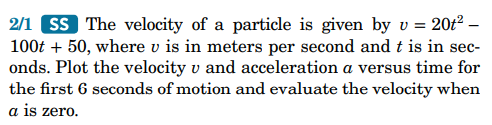

v = 20*t^2-100*t+50

$a = \frac{dv}{dt}=\dot{v} \rightarrow$ a = 40*t-100

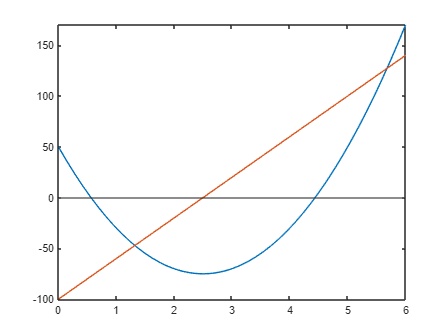

v = @(t) 20*t.^2-100.*t+50;
a = @(t) 40.*t-100;

fplot(v,[0 6]) 
hold on
xline(0)
yline(0)
fplot(a,[0 6]) 
hold off

## ***Opgave 2/9:***

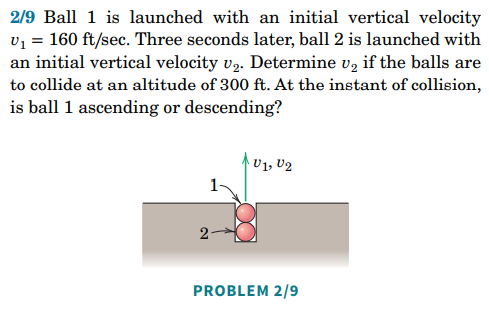

Da vi godt kan lide SI enheder, så konverter vi ft til m:

- 160 ft/sec = 48,77 m/s

- 300 ft = 91,44 m

Vi kan bestemme tiden det tager for bold 1 at flyve de 300 meter via sted formlen.

Når vi har tiden, så kan vi finde hastigheden for bold 2.

clear all
syms t v2;

% De kendte værdier:
v0 = 48.77;
g = -9.82;

% Strækningsformlen for bold 1:
s_b1 = v0*t+(1/2)*g*t^2;

% Udregning af tiden til 91.44 meter på vej ned:
s = v0*t+(1/2)*g*t^2-91.44;
eq = vpa(solve(s,t),3);
t_b10 = 7.42;

% Da vi har tiden til 91.44 meter, så kan vi bestemme hastigheden som bold
% 2 skal have ved at begrænse tiden med 3 sek og solve for v2.

% Hastigheden via strækningen:
v_b2 = v2*(t_b10-3)+(1/2)*g*(t_b10-3)^2-91.44;
eq2 = vpa(solve(v_b2,v2),3)

$$eq2 = 42.4$$

## ***Opgave 2/17***

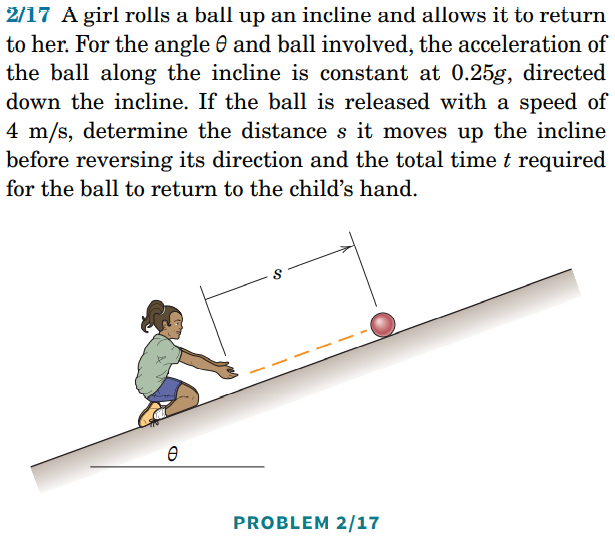

Informationer:

- Accelerationen er: a = 0.25 * g

- Hastigheden er: v0 = 4 

Der skal bestemmes:

- Strækningen bolden bevæger sig op af bakken, s.

- Bestem tiden til nul.

Til denne opgave skal vi anvende strækningsformlen:

- 
$$s = s_{0} + v_{0}*t+\frac{1}{2}*a*t^2$$
 

clear all

syms t;

a = 0.25 * (-9.81)

a = -2.4525

v0 = 4

v0 = 4

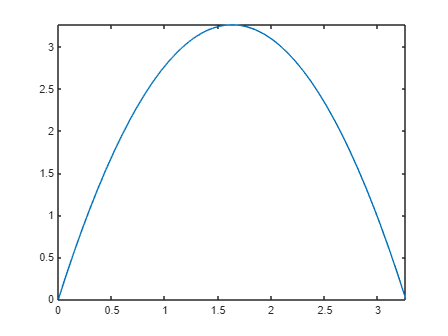


% Vi opsætter strækningsfunktionen, hvorefter vi plotter den:
s_bold = v0*t + (1/2)*a*t^2;
fplot(s_bold,[0 3.26]);

% Vi opsætter en der udregner tiden til nul:
tid_bold0 = vpa(simplify(solve(s_bold,t)),3);
% Vi må antage, at den længste strækning som bolden når, før den kører tilbage, er ved tid-halve:
tidHalve = 3.26/2;
s = v0*tidHalve + (1/2)*a*tidHalve^2

s = 3.2620

## ***Opgave 2/39***

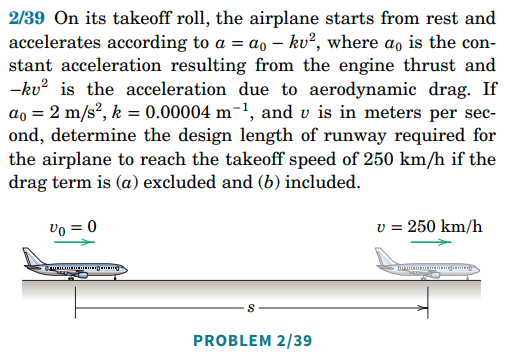

Informationer:

- Accelerationen: $a = a_0 - k*v^2$

- Luftmodstanden: $k = 0.00004$

- Den konstante acceleration: $a_0 = 2 \frac{m}{s}$

- Take off hastigheden er: $v_{takeoff} = 250 km/h \rightarrow \frac{250*1000}{3600} = 69.44 \frac{m}{s}$

Det der skal bestemmes:

- Længden som kørebanen skal have, hvis luftmodstanden er regnet med og uden.

Det som vi skal vide for at løse opgaven:

- Tiden det tager at nå de 69.44 m/s.

clear all
syms t;

a0 = 2;
k = 0.00004;
v_takeoff = 69.44444;

% Vi starter med at finde tiden til hastigheden takeoff uden bidrag fra luftmodstanden:
TidTakeoff = a0*t - v_takeoff;
eq = vpa(solve(TidTakeoff,t),3);
t_takeoff = 34.7;

% Nu kan vi finde strækningen, som vores fly bevæger sig, før det når vores
% hastighed:
s_udenModstand = ((1/2)*a0*t_takeoff^2); % 1204.1 meter
s_udenModstand2 = v_takeoff^2/(2*a0); % 1205.6 meter

% Nu kan vi medtage vores luftmodstand:
% Igen starter vi med at bestemme tiden til 250 km/h er nået:
% Vi kan finde tiden ved at isolere for den i hastighedsformlen. 
% Når vi kender den ønskede hastighed, så kan vi flytte svaret over på
% højresiden, hvor vi så kan solve for tiden til at acceleratioen med den
% fratrukkede hastighed giver nul.
% Dette resultat fortæller, hvor langtid det tager vores acceleration at nå
% vores ønskede hastighed.
TidModstand = a0*t - k*(v_takeoff^2)*t - v_takeoff;
eq2 = vpa(solve(TidModstand,t),8); 
TidTakeoffModstand = 38.42869;

% Indsætter vi tiden i strækning/flytningsformlen, så kan vi finde den
% ønskede længde:
s = vpa(0.5*v_takeoff*TidTakeoffModstand, 8)

$$s = 1334.3294$$

# Kapitel 2: Retlinet bevægelse / Kinematics of Particles

# Undervisning D. 21/11 - 22

## Opgave 6/89

syms g m l w

d = l/4;
IG = 1/12 * m * l^2;
I0 = IG + d^2 * m;
U1_2 = m * g * l/4;

eq = U1_2 == 1/2 * I0 * w^2

$$eq = \frac{g\,l\,m}{4}=\frac{7\,l^{2}\,m\,w^{2}}{96}$$

w = vpa(simplify(solve(eq,w)),5)

$$w = \left(\begin{array}{c} -\frac{1.8516\,\sqrt{g}}{\sqrt{l}}\\ \frac{1.8516\,\sqrt{g}}{\sqrt{l}} \end{array}\right)$$

## Opgave 6/91

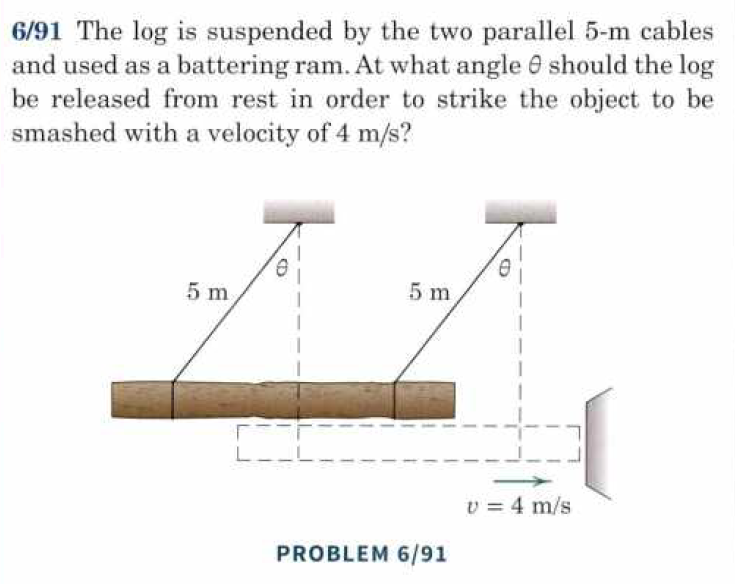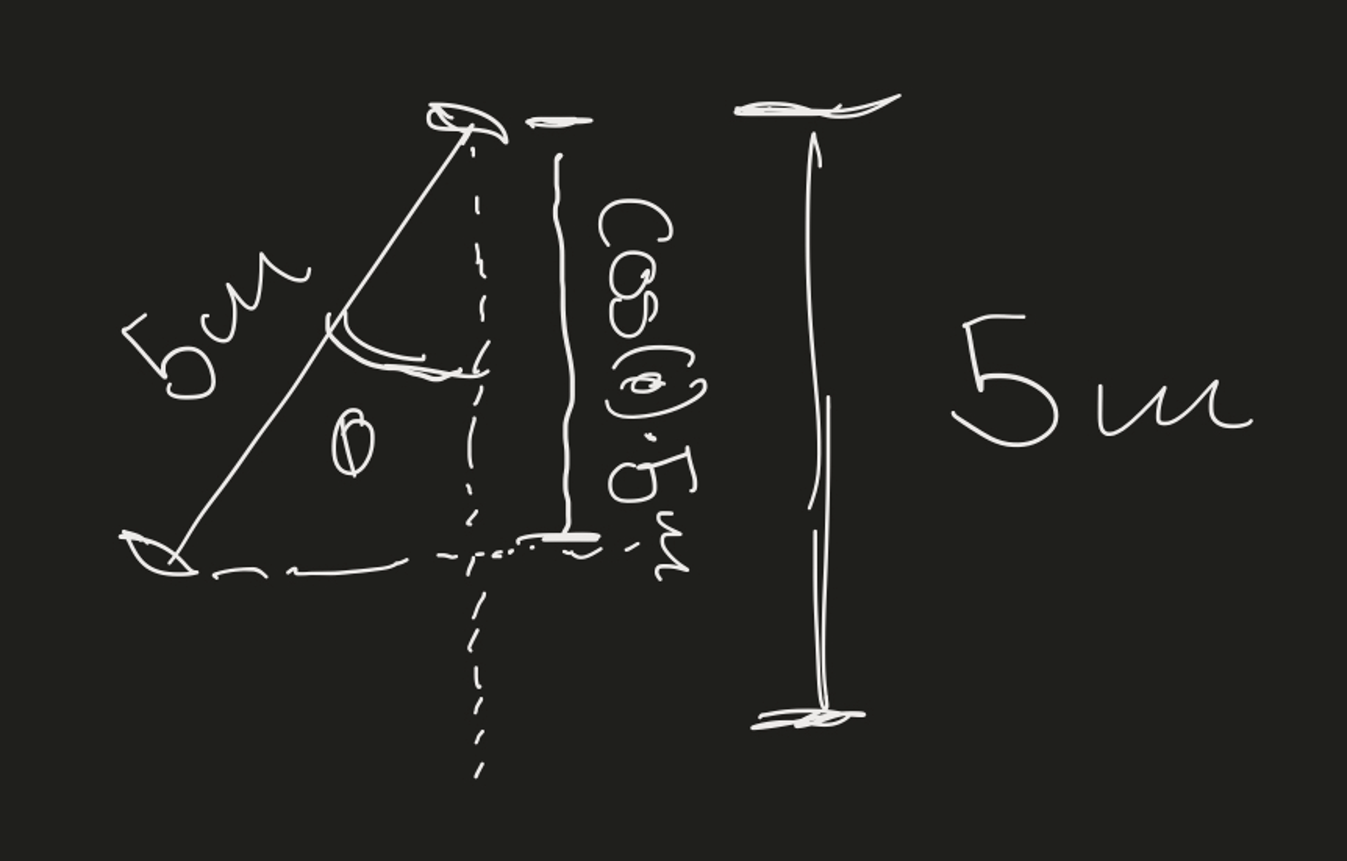

Vi har en bjælke, som har en snor, der er 5 meter lang fra origo. Den er trukket tilbage/hævet x-afstand, hvoraf den også er hævet y-afstand.

Dette definerer vi som første tilfælde.

Næste tilfælde befinder sig x-afstand væk og 5 meter fra origo.

Vi ønsker at kende:

- Vinklen mellem de to tilfælde, som er defineret. 